clc; clear; addpath z_toolbox;
addpath E:\IEDpropagation\z_toolbox\Violinplot;
path = 'step3_IEDtw_polyfit_diffTD';
TDstr = {'5d0', '5d2', '5d4', '5d6', '5d8', '6d0', '6d2', '6d4', '6d6', '6d8', ...
        '7d0', '7d2', '7d4', '7d6', '7d8', '8d0', '8d2', '8d4', '8d6', '8d8', '9d0'};
TD = 5:0.2:9;
errorShadowX = [TD, fliplr(TD)];
for nTD = 1:length(TD)
    load(fullfile(path, ['IEDtw_meth-none_TD-', TDstr{nTD}, '_polyfit.mat']), ...
        'adjR2_twDED');
    Vmean(nTD, :) = mean(adjR2_twDED, 1, 'omitnan'); 
    Vstd(nTD, :) = std(adjR2_twDED, 0, 1, 'omitnan');
end
figure('Units', 'centimeters', 'Position', [5, 5, 36, 20]);
subplot(2, 3, [1, 4]);
for n = 1:6
    plot(TD, Vmean(:, n), 'LineStyle', '-', 'LineWidth', 2); 
    hold on;
end
hold off;
legend({'1st', '2nd', '3rd', '4th', '5th', '6th'}, 'Box', 'off');
xlim([5, 9]);
xlabel('IED Detection Peak-to-Peak threshold'); 
ylabel("Adjusted R^2");
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## IED TW rate VS. IED TW delay

clc; clear;
load(fullfile('step4_IEDtw_polyfit_TD6d0',  'IEDtw_meth-None_TD-6d0.mat'));
nS = 13; subID = 'sub-0014';
% Load Euclidean distance matrix for current subject
load(fullfile('step2_channelDistance', [subID,'_EuclideabDistanceMatrix.mat']));
% Extract IED traveling wave delays, rate and Euclidean distance
IEDtwD = IEDtw(nS).indirectTransferDelayMatrix;
IEDtwR = IEDtw(nS).indirectTransferRateMatrix;
Mask = IEDtwR;
Mask = Mask - diag(diag(Mask));
Mask(isnan(Mask)) = 0;
Mask(Mask<0.1) = 0;
ED = DistanceWorld(Mask>0);
IEDtwD = IEDtwD(Mask>0);
IEDtwR = IEDtwR(Mask>0);
IEDtwR = log(IEDtwR);
order = 6;
% Remove distance effect from log-rates using polynomial fit
[polyModel, ~, ~] = f_polyfit(ED, IEDtwR, order);
IEDtwR_rED = polyModel.residual+polyModel.p(end);
% Remove distance effect from delays using polynomial fit
[polyModel, ~, ~] = f_polyfit(ED, IEDtwD, order);
IEDtwD_rED = polyModel.residual+polyModel.p(end);
x = IEDtwR_rED; y = IEDtwD_rED;
% Correlation between residuals (rate vs delay)
[r, p] = corr(x, y, "type", "Spearman");
disp(r); disp(p);

   -0.3521

  1.5881e-165



[~, Curve, ~] = f_polyfit(x, y, 1);
subplot(2, 3, 2);
f_densityScatter(x, y, 2); 
hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]);
ylim([min(y), max(y)]);
xlabel('log(IED-TW Rate (n/min))'); 
ylabel('IED-TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Spearman correlation R of IED TW delay and rate

clc; clear;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), ...
    'R_twDR_rED');
R_twDR_rED_true = R_twDR_rED(:, 6);
disp(mean(R_twDR_rED_true)); disp(std(R_twDR_rED_true));

   -0.2445

    0.1651



trueStr = cell(length(R_twDR_rED_true), 1);
for n = 1:length(trueStr)
    trueStr{n} = 'Empirical';
end
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit_distanceVSdelay_rateVSdelay.mat'), ...
    'R_twDR_rED');
R_twDR_rED_null = mean(R_twDR_rED, 3);
R_twDR_rED_null = mean(R_twDR_rED_null(:, 6), 2);
disp(mean(R_twDR_rED_null)); disp(std(R_twDR_rED_null));

   -0.0843

    0.1621



nullStr = cell(length(R_twDR_rED_null), 1);
for n = 1:length(nullStr)
    nullStr{n} = 'Null';
end
R = [R_twDR_rED_true; R_twDR_rED_null];
Origin = [trueStr; nullStr];
subplot(2, 3, 5);
vs = violinplot(R, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Empirical', 'Null'}, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]); 
ylabel('Spearman Correlation');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
x = R_twDR_rED_true(:); 
y = R_twDR_rED_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; 
cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 9.3678e-06 z = -4.4313 Cliff Delta = -0.53101 df = 92


## SC Strength VS IED TW Delay

clc;clear;
load(fullfile('step2_fiberTrack', 'FiberMatrix_ncount_length_qa_allsubject.mat'), 'fiberCount');
load(fullfile('step4_IEDtw_polyfit_TD6d0', 'IEDtw_meth-None_TD-6d0.mat'));
nS = 13; subID = 'sub-0014';
% Load Euclidean distance matrix for current subject
load(fullfile('step2_channelDistance', [subID,'_EuclideabDistanceMatrix.mat']));
% Extract fiber count data
fibN = fiberCount{nS};
% Extract IED traveling wave data
IEDtwD = IEDtw(nS).indirectTransferDelayMatrix;
IEDtwR = IEDtw(nS).indirectTransferRateMatrix;
Mask = IEDtwR;
Mask = Mask - diag(diag(Mask));
Mask(isnan(Mask)) = 0;
Mask(Mask<0.1) = 0;
Mask(fibN==0) = 0;
ED = DistanceWorld(Mask>0);
IEDtwD = IEDtwD(Mask>0);
fibN = fibN(Mask>0);
fibN = log(fibN);
%% Correlation Analysis
% Raw correlation between fiber count and delay
[R_fibNtwD(nS), P_fibNtwD(nS)] = corr(fibN, IEDtwD, "type", "Spearman");
order = 6;
% Remove distance effect from fiber count using polynomial fit
[polyModel, ~, ~] = f_polyfit(ED, fibN, order);
fibN_rED = polyModel.residual+polyModel.p(end);
% Remove distance effect from delays using polynomial fit
[polyModel, ~, ~] = f_polyfit(ED, IEDtwD, order);
IEDtwD_rED = polyModel.residual+polyModel.p(end);
x = fibN_rED; y = IEDtwD_rED;
% Correlation between residuals (rate vs delay)
[r, p] = corr(x, y, "type", "Spearman");
disp(r); disp(p);

   -0.1645

   2.2865e-06



[~, Curve, ~] = f_polyfit(x, y, 1);
subplot(2, 3, 3);
f_densityScatter(x, y, 2); 
hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]);
ylim([min(y), max(y)]);
xlabel('SC Strength');
ylabel('IED-TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Spearman R between SC Strength and IED-TW Delay

clc; clear;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), ...
    'R_fibNtwD_rED');
R_fibNtwD_rED_true = R_fibNtwD_rED';
R_fibNtwD_rED_true(R_fibNtwD_rED_true == 0) = [];
disp(mean(R_fibNtwD_rED_true)); disp(std(R_fibNtwD_rED_true));

   -0.0576

    0.0786



trueStr = cell(length(R_fibNtwD_rED_true), 1);
for n = 1:length(trueStr)
    trueStr{n} = 'Empirical';
end
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), ...
    'R_fibNtwD_rED');
R_fibNtwD_rED_null = mean(R_fibNtwD_rED, 2);
R_fibNtwD_rED_null(R_fibNtwD_rED_null == 0) = [];
disp(mean(R_fibNtwD_rED_null)); disp(std(R_fibNtwD_rED_null));

   -0.0064

    0.0634



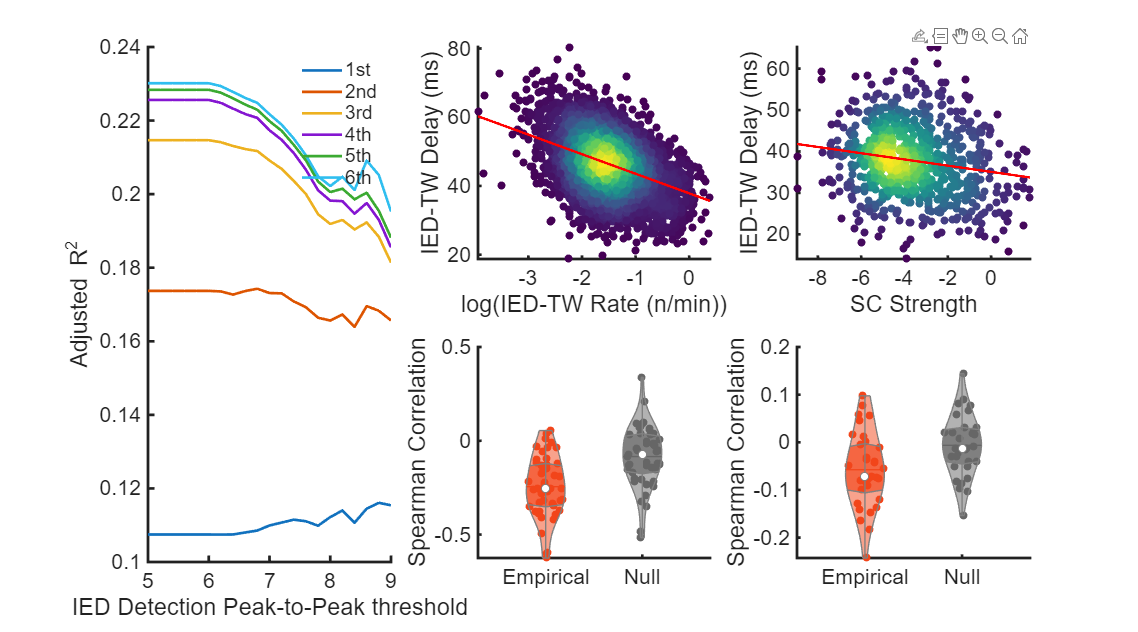

nullStr = cell(length(R_fibNtwD_rED_null), 1);
for n = 1:length(nullStr)
    nullStr{n} = 'Null';
end
R = [R_fibNtwD_rED_true; R_fibNtwD_rED_null];
Origin = [trueStr; nullStr];
subplot(2, 3, 6);
vs = violinplot(R, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Empirical', 'Null'}, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]); 
ylabel('Spearman Correlation');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

x = R_fibNtwD_rED_true(:);
y = R_fibNtwD_rED_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval;
cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 0.0063025 z = -2.7316 Cliff Delta = -0.3921 df = 64
